%% MathTools Lab 1 (HW0)
%Date: Sep 5th 2024

%% Question 1
%a)
%Testing 1: Project [3, 4] onto [0.6, 0.8]
v = [3, 4];
u = [0.6, 0.8];

length_projected_vector = project(v, u);
disp(length_projected_vector); 

    2.7785




%Testing 1: Project [7, 8, 9] onto [0, 0, 1]
v = [7, 8, 9];
u = [0, 0, 1];

length_projected_vector = project(v, u);
disp(length_projected_vector); 

     9





%% Question 1
%b)
%Testing Gram–Schmidt process
v = [3, 4];
u = [0.6, 0.8];
[coordinates_v, matrix_uw] = changeOfCoords(v, u); 
disp('Coordinates of v in the new coordinate system:');

Coordinates of v in the new coordinate system:


disp(coordinates_v);

    5.0000
   -0.0000




disp('Matrix [u, w]:');

Matrix [u, w]:


disp(matrix_uw);

    0.6000   -0.8000
    0.8000    0.6000



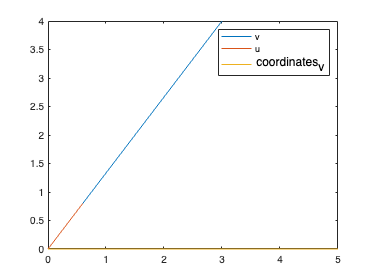


plot([0,v(1)],[0,v(2)]);hold on;
plot([0,u(1)],[0,u(2)]);hold on;
plot([0,coordinates_v(1)], [0,coordinates_v(2)]); hold on;
legend('v','u','coordinates_v');


testing = (matrix_uw * coordinates_v)';
disp(testing);

    3.0000    4.0000



%% Functions

%1a)

function length_projected_vector = project(v, u)

%ensure that u is a unit factor
if norm(u) ~= 1
    error('change u to a unit vector')
end

%projecting v onto u
%proj_v_on_u = dot(v, u) * u;
proj_v_on_u = (v.*u).*u;
%length_projected_vector = norm(proj_v_on_u); 
length_projected_vector = sqrt(sum(proj_v_on_u.^2));

end

%1b)
function [coordinates_v, matrix_uw] = changeOfCoords(v, u)
% v: created orthogonal vector in a new ”coordinate system”
% u: one of the new axes (will be normalized)

%making u an unit vector
%u = u / norm(u);
u = u / sqrt(sum(u.^2));


%creating an orthogonal unit vector w
w = [-u(2), u(1)];

%List the matrix
matrix_uw = [u(:), w(:)]; 

%compute the coordinates
coordinates_v = matrix_uw \ v(:);
end 